# Actividad 4 | Robot Angular 3 GDL

Oscar Ortiz Torres A01769292

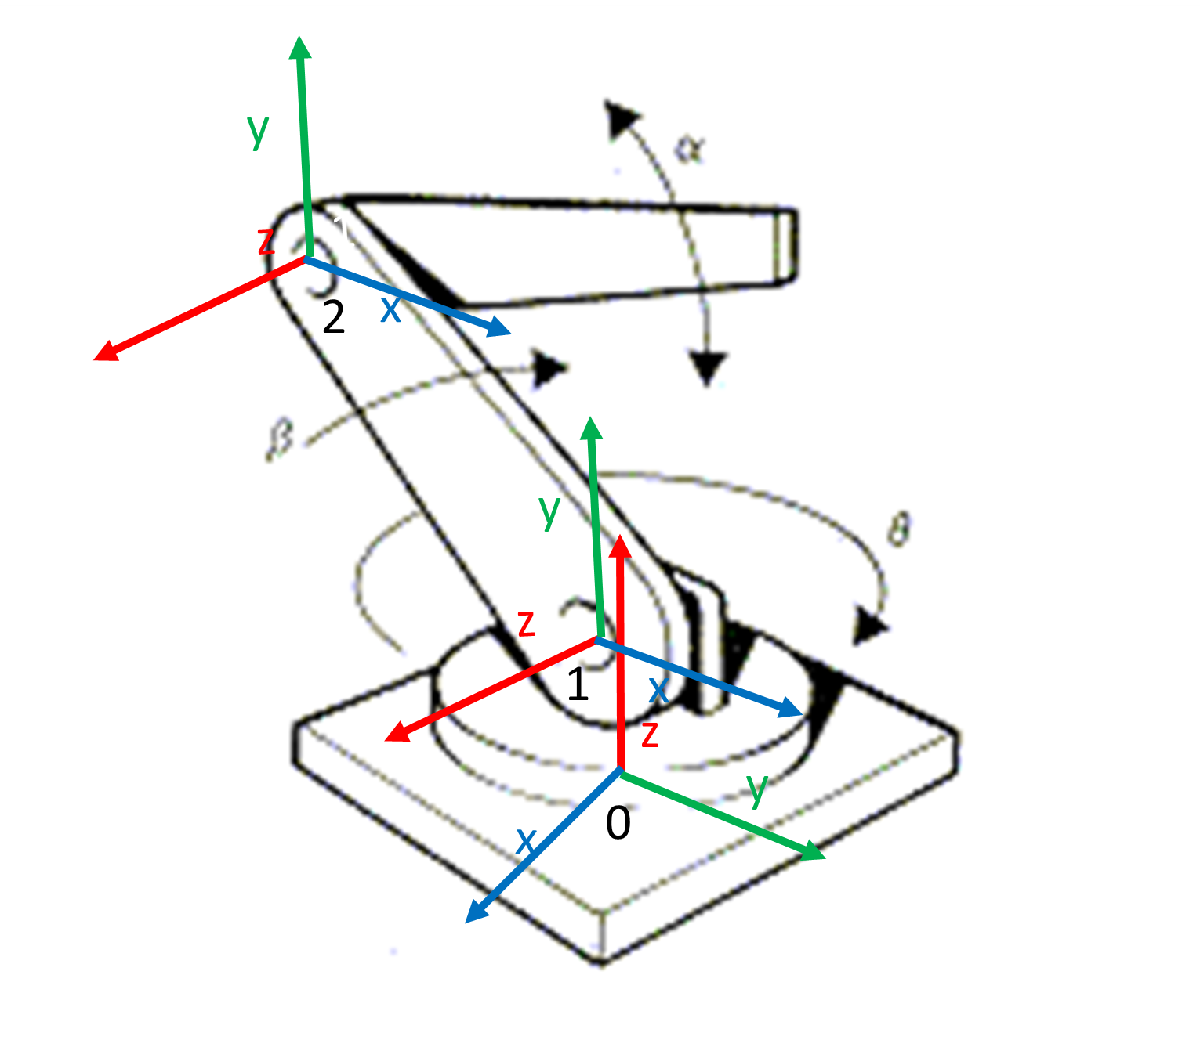

Se declaran las distancias y ángulos de las 3 articulaciones rotacionales

clear all
close all
clc

syms theta(t) beta(t) alpha(t) l0 l1 l2 t

% Configuración del robot, de cada GDL
RP = [0 0 0];

% Creación del vector de coordenadas articulares
Q = [theta beta alpha];

% Creación del vector de velocidades generalizadas
Qp = diff(Q, t);

% Número de grados de libertad  
GDL = size(RP, 2);
GDL_str = num2str(GDL);

## Articulación 0

Al girar unicamente sobre la base, la distancia que exista entre la articulación 0 y 1 se queda como constante en Z de su vector de posición.

% Posición de la articulación 0 a 1
P(:,:,1) = [
             0;
             0;
             l0
           ];

Para pasar del sistema de coordenadas 0 a 1 es necesario realizar 2 transformaciones de rotación, una de +90° en el eje X y otra de +90° en Y, aplicandolas a la matriz de rotación en Z propia del movimiento de la articulación. Los signos de las transformaciones son positivos por la regla de la mano derecha. 

% Matriz de rotación de la junta 0 a 1
R(:,:,1) = [
             cos(theta)   -sin(theta)     0;
             sin(theta)    cos(theta)     0;
             0           0            1
             ]*rotX(90)*rotY(90);

## Articulación 1

Después de la transformación anterior, la rotación en Z afecta directamente a la posición final del eslabón, por lo que se necesita desomponer en su componente en X y su componente en Y en su vector de posición.

% Posición de la articulación 1 a 2
P(:,:,2) = [
             l1*cos(beta);
             l1*sin(beta);
             0
           ];

Al no existir un nuevo sistema de coordenadas para manejar el siguiente eslabón, se mantiene la matriz de rotación en Z propia del movimiento de la articulación.

% Matriz de rotación de la junta 1 a 2
R(:,:,2) = [
             cos(beta)   -sin(beta)     0;
             sin(beta)    cos(beta)     0;
             0           0            1
             ];

## Articulación 2

Similar a la articulación anterior, la rotación en Z afecta directamente a la posición del efector final, por lo que se necesita desomponer en su componente en X y su componente en Y en su vector de posición.

% Posición de la articulación 2 a 3
P(:,:,3) = [
             l2*cos(alpha);
             l2*sin(alpha);
             0
           ];

Al no existir un nuevo eslabón, se mantiene la matriz de rotación en Z propia del movimiento de la articulación.

% Matriz de rotación de la junta 2 a 3
R(:,:,3) = [
             cos(alpha)   -sin(alpha)     0;
             sin(alpha)    cos(alpha)     0;
             0           0            1
             ];

## Matrices

% Creación de vector de ceros
vector_zeros = zeros(1,3);

% Inicialización de las matrices de Transformación Homogenea locales
A(:, :, GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de las matrices de tranformación Homogenea globales
T(:,:,GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de los vectores de posición vistos desde el marco de
% referencia inercial
PO(:,:,GDL) = P(:,:,GDL);

% Inicialización de las matrices de rotación vistas desde el marco de
% referencia inercial
RO(:,:,GDL) = R(:,:,GDL);

for i = 1:GDL
    i_str = num2str(i);

    % Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([ ...
                         R(:,:,i)       P(:,:,i); ...
                         vector_zeros   1 ...
                        ]); A(:,:,i)

    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); % Caso específico cuando i=1 nos marcaría error en try
    end

    %disp(strcat('Matruz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i));

    % Obtención de la matriz de rotación "RO" y el vector de traslación PO
    % de la matriz de transformación homogenea global T(:,:, GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
end

Matriz de Transformación local A1


$$ans = \left(\begin{array}{cccc} -\sin\left(\theta \left(t\right)\right) & 0 & \cos\left(\theta \left(t\right)\right) & 0\\ \cos\left(\theta \left(t\right)\right) & 0 & \sin\left(\theta \left(t\right)\right) & 0\\ 0 & 1 & 0 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A2


$$ans = \left(\begin{array}{cccc} \cos\left(\beta \left(t\right)\right) & -\sin\left(\beta \left(t\right)\right) & 0 & l_{1}\,\cos\left(\beta \left(t\right)\right)\\ \sin\left(\beta \left(t\right)\right) & \cos\left(\beta \left(t\right)\right) & 0 & l_{1}\,\sin\left(\beta \left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A3


$$ans = \left(\begin{array}{cccc} \cos\left(\alpha \left(t\right)\right) & -\sin\left(\alpha \left(t\right)\right) & 0 & l_{2}\,\cos\left(\alpha \left(t\right)\right)\\ \sin\left(\alpha \left(t\right)\right) & \cos\left(\alpha \left(t\right)\right) & 0 & l_{2}\,\sin\left(\alpha \left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

En la matriz de transformación global del sistema, en la matriz de rotación se observa la propagación de las transformación que se realizaron para pasar del sistema 0 al 1, por otro lado, el vector de posisión involucra en en sus diferentes ejes a los 3 angulos del sistema, mientras que en X y Y solo involucra a las distancias del eslabon 1 y 2, pues son las que rotan en el mismo plano.

disp('Matriz de Transformación global'); T(:,:,GDL)

Matriz de Transformación global


$$ans = \begin{array}{l} \left(\begin{array}{cccc} -\sin\left(\theta \left(t\right)\right)\,\cos\left(\sigma_{2}\right) & \sin\left(\theta \left(t\right)\right)\,\sin\left(\sigma_{2}\right) & \cos\left(\theta \left(t\right)\right) & -\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\\ \cos\left(\theta \left(t\right)\right)\,\cos\left(\sigma_{2}\right) & -\cos\left(\theta \left(t\right)\right)\,\sin\left(\sigma_{2}\right) & \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right)\,\sigma_{1}\\ \sin\left(\sigma_{2}\right) & \cos\left(\sigma_{2}\right) & 0 & l_{0}+l_{1}\,\sin\left(\beta \left(t\right)\right)+l_{2}\,\sin\left(\sigma_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,\cos\left(\beta \left(t\right)\right)+l_{2}\,\cos\left(\sigma_{2}\right)\\ \sigma_{2}=\alpha \left(t\right)+\beta \left(t\right) \end{array}$$

% Inicialización de jacobianos analíticos (lineal y angular)
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

for k = 1:GDL
    if(RP(k) == 0)
        % Para las articulaciones rotacionales
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0 0 1], PO(:,:,GDL)); % Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k) = [0 0 1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
    elseif(RP(k) == 1)
        % Para las articulaciones prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
            Jw_a(:,k) = [0 0 0];
    end
end

## Despliegue

disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); V = simplify(Jv_a * Qp')

Velocidad lineal obtenida mediante el Jacobiano lineal


$$V(t) = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{5}-\sigma_{3}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{4}+l_{2}\,\sigma_{2}\,\sin\left(\theta \left(t\right)\right)\,\sin\left(\sigma_{6}\right)\\ -\sigma_{1}\,\cos\left(\theta \left(t\right)\right)\,\sigma_{5}-\sigma_{3}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{4}-l_{2}\,\sigma_{2}\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\sigma_{6}\right)\\ l_{1}\,\sigma_{1}\,\cos\left(\beta \left(t\right)\right)+l_{2}\,\sigma_{2}\,\cos\left(\sigma_{6}\right)+l_{2}\,\sigma_{1}\,\cos\left(\sigma_{6}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}\beta \left(t\right)}\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}\alpha \left(t\right)}\\ \sigma_{3}=\bar{\frac{\partial }{\partial t}\theta \left(t\right)}\\ \sigma_{4}=l_{1}\,\cos\left(\beta \left(t\right)\right)+l_{2}\,\cos\left(\sigma_{6}\right)\\ \sigma_{5}=l_{1}\,\sin\left(\beta \left(t\right)\right)+l_{2}\,\sin\left(\sigma_{6}\right)\\ \sigma_{6}=\alpha \left(t\right)+\beta \left(t\right) \end{array}$$

disp('Velocidad angular obtenida mediante el Jacobiano angular'); W = simplify(Jw_a * Qp')

Velocidad angular obtenida mediante el Jacobiano angular


$$W(t) = \left(\begin{array}{c} \cos\left(\theta \left(t\right)\right)\,\left(\bar{\frac{\partial }{\partial t}\alpha \left(t\right)}+\bar{\frac{\partial }{\partial t}\beta \left(t\right)}\right)\\ \sin\left(\theta \left(t\right)\right)\,\left(\bar{\frac{\partial }{\partial t}\alpha \left(t\right)}+\bar{\frac{\partial }{\partial t}\beta \left(t\right)}\right)\\ \bar{\frac{\partial }{\partial t}\theta \left(t\right)} \end{array}\right)$$

## Funciones de rotacion

function r_x = rotX(th)
    r_x = [1 0 0; 0 cosd(th) -sind(th); 0 sind(th) cosd(th)];
end

function r_y = rotY(th)
    r_y = [cosd(th) 0 sind(th); 0 1 0; -sind(th) 0 cosd(th)];
end

function r_z = rotZ(th)
    r_z = [cosd(th) -sind(th) 0; sind(th) cosd(th) 0; 0 0 1];
end